load("test3Data.mat")

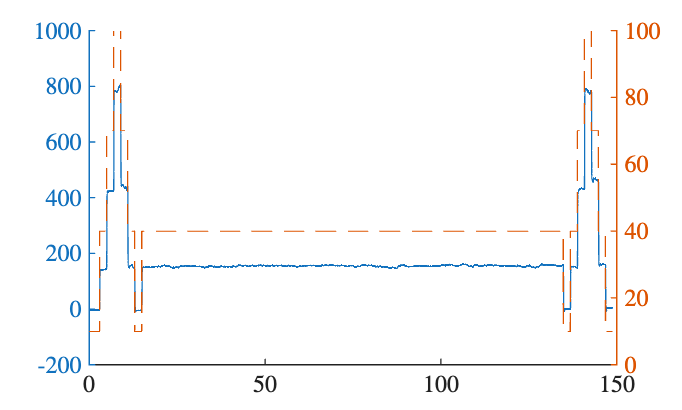

figure, clf, hold on
yyaxis left
plot(rawTime, rawThrust)
yyaxis right
plot(rawTime, rawThrottle, "--")
ylim([0 100])
hold off

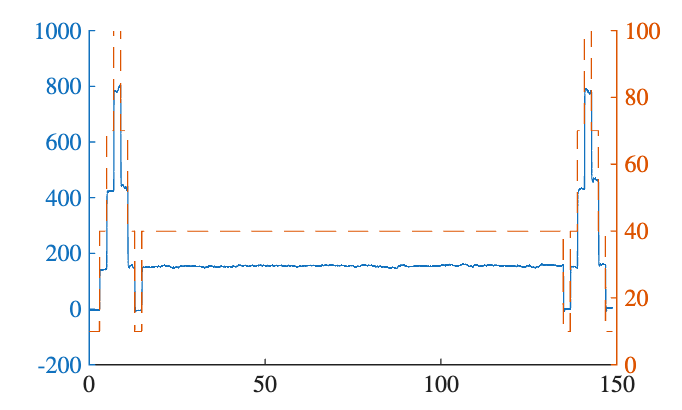


[thrust,time] = resample(rawThrust, rawTime, 80);

throttle = zeros(length(time),1);
throttle(1:235) = 10;
throttle(236:395) = 40;
throttle(396:555) = 70;
throttle(556:715) = 100;
throttle(716:875) = 70;
throttle(876:1035) = 40;
throttle(1036:1195) = 10;
throttle(1196:10785) = 40;
throttle(10786:10944) = 10;
throttle(10945:11104) = 40;
throttle(11105:11264) = 70;
throttle(11265:11424) = 100;
throttle(11425:11584) = 70;
throttle(11585:11744) = 40;
throttle(11745:end) = 10;

figure, clf, hold on
yyaxis left
plot(rawTime, rawThrust)
yyaxis right
plot(rawTime, rawThrottle, "--")
plot(time, throttle, "--")
ylim([0 100])
hold off

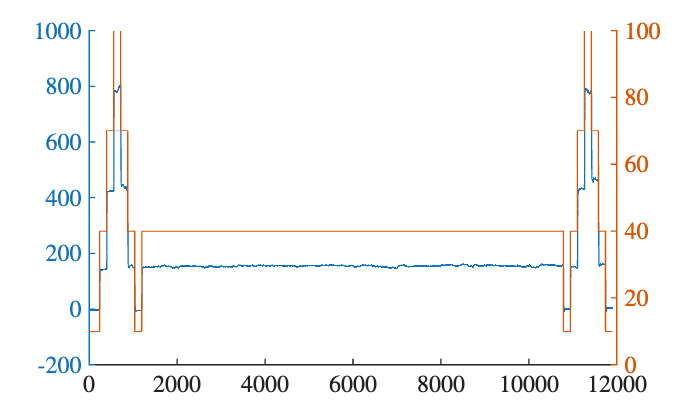


figure, clf, hold on
yyaxis left
plot(thrust)
yyaxis right
plot(throttle)
hold off


% 10-40
data = iddata(thrust(200:300)-thrust(200),throttle(200:300)-throttle(200),1/80)

data = Time domain data set with 101 samples.
Sample time: 0.0125 seconds           
                                      
Outputs      Unit (if specified)      
   y1                                 
                                      
Inputs       Unit (if specified)      
   u1                                 
                                      
Data Properties

C10_40 = procest(data,'P1D')


C10_40 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 4.7686                  
       Tp1 = 0.0296                  
        Td = 0.055525                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.43%                     
FPE: 3.346, MSE: 3.153                             
 
Model Properties


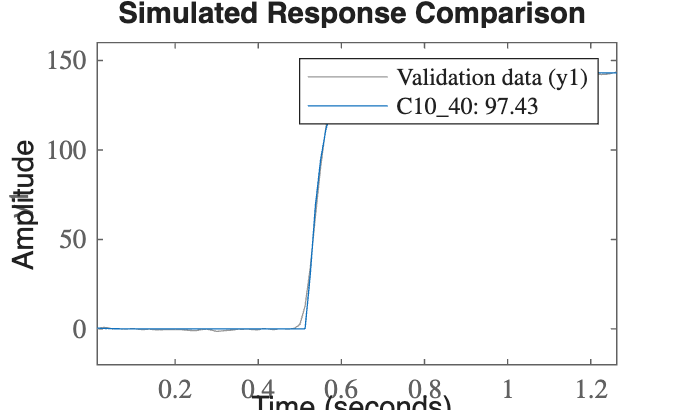

compare(C10_40,data);


% 40-70
data = iddata(thrust(360:460)-thrust(360),throttle(360:460)-throttle(360),1/80);
C40_70 = procest(data,'P1D')


C40_70 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 9.3538                  
       Tp1 = 0.032415                
        Td = 0.043488                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.36%                     
FPE: 13.3, MSE: 12.53                              
 
Model Properties


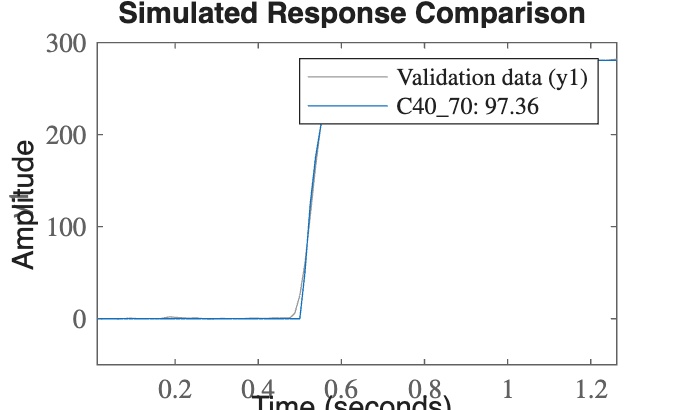

compare(C40_70,data);


% 70-100
data = iddata(thrust(520:620)-thrust(520),throttle(520:620)-throttle(520),1/80);
C70_100 = procest(data,'P1D')


C70_100 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 11.971                  
       Tp1 = 0.024314                
        Td = 0.044075                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.82%                     
FPE: 15.12, MSE: 14.24                             
 
<a href="matlab:if exist('C70_100','var'), if isa(C70_100,'idproc'), disp(' '); disp(get(C70_100)), else disp(' '); disp('Unable to display properties for variable C70_100 because it is no longer a/an idproc object.');, end, else matlab.graphics.internal.getForDisplay('C70_100'), end">Model Properties<

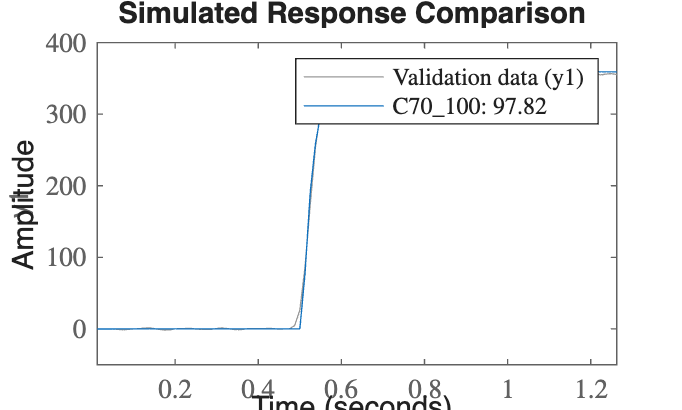

compare(C70_100,data);


% 100-70
data = iddata(thrust(680:780)-thrust(680),throttle(680:780)-throttle(680),1/80);
C100_70 = procest(data,'P1D')


C100_70 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 11.879                  
       Tp1 = 0.032009                
        Td = 0.033575                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.13%                     
FPE: 25.53, MSE: 24.05                             
 
<a href="matlab:if exist('C100_70','var'), if isa(C100_70,'idproc'), disp(' '); disp(get(C100_70)), else disp(' '); disp('Unable to display properties for variable C100_70 because it is no longer a/an idproc object.');, end, else matlab.graphics.internal.getForDisplay('C100_70'), end">Model Properties<

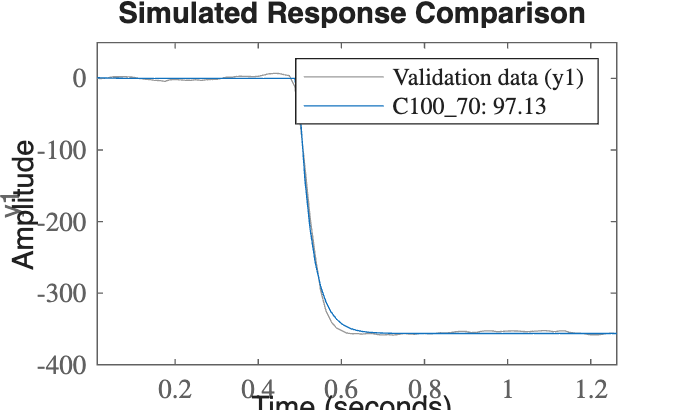

compare(C100_70,data);


% 70-40
data = iddata(thrust(840:940)-thrust(840),throttle(840:940)-throttle(840),1/80);
C70_40 = procest(data,'P1D')


C70_40 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 9.4853                  
       Tp1 = 0.034384                
        Td = 0.034212                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 96.53%                     
FPE: 23.51, MSE: 22.15                             
 
Model Properties


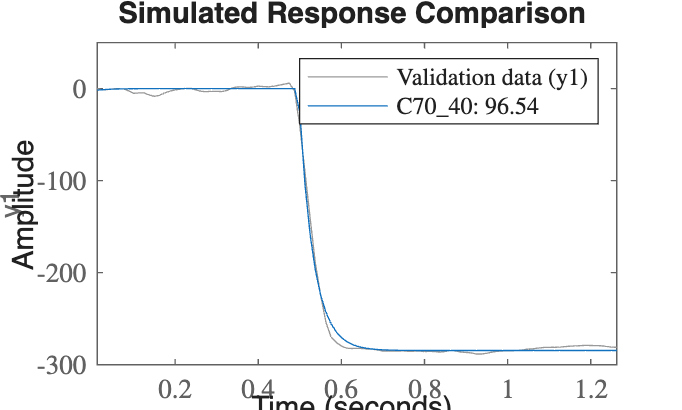

compare(C70_40,data);


% 40-10
data = iddata(thrust(1000:1100)-thrust(1000),throttle(1000:1100)-throttle(1000),1/80);
C40_10 = procest(data,'P1D')


C40_10 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 5.1541                  
       Tp1 = 0.036824                
        Td = 0.029925                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 96.48%                     
FPE: 7.008, MSE: 6.604                             
 
Model Properties


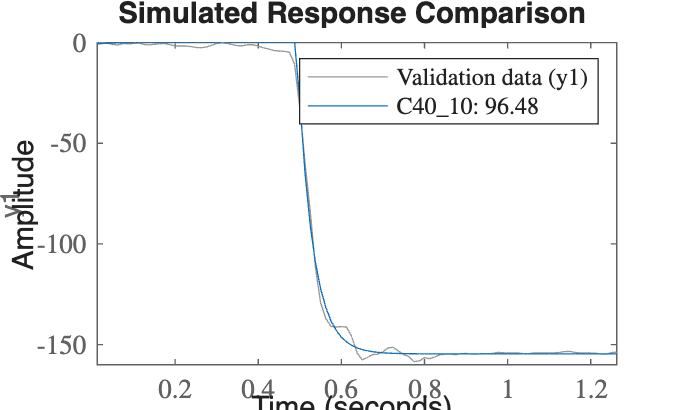

compare(C40_10,data);



% HOT

% 10-40
data = iddata(thrust(10910:11010)-thrust(10910),throttle(10910:11010)-throttle(10910),1/80);
H10_40 = procest(data,'P1D')


H10_40 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 5.0671                  
       Tp1 = 0.034659                
        Td = 0.054775                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.49%                     
FPE: 3.539, MSE: 3.334                             
 
Model Properties


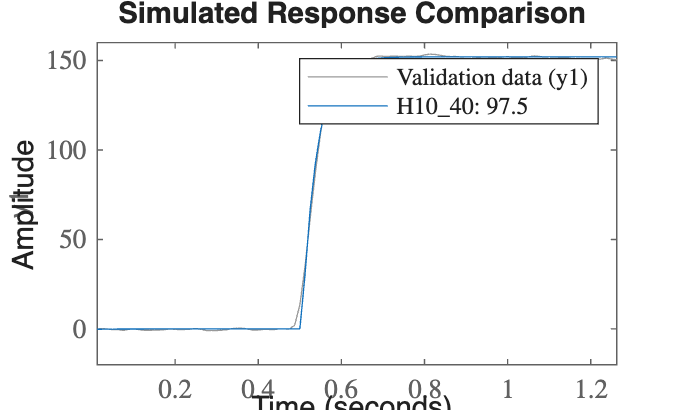

compare(H10_40,data);


% 40-70
data = iddata(thrust(11070:11170)-thrust(11070),throttle(11070:11170)-throttle(11070),1/80);
H40_70 = procest(data,'P1D')


H40_70 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 9.3218                  
       Tp1 = 0.041779                
        Td = 0.045425                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 96.94%                     
FPE: 17.63, MSE: 16.62                             
 
Model Properties


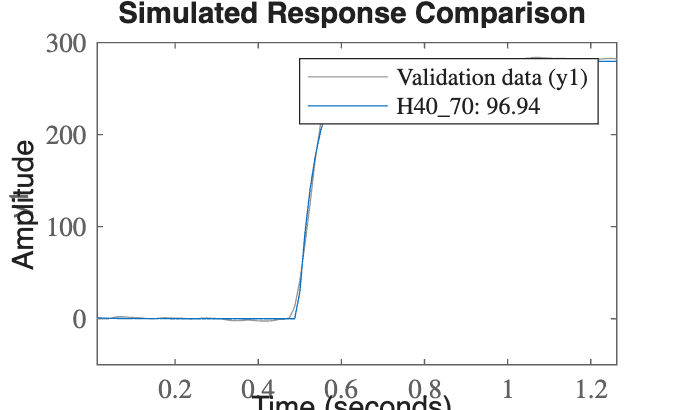

compare(H40_70,data);


% 70-100 HOT
data = iddata(thrust(11230:11330)-thrust(11230),throttle(11230:11330)-throttle(11230),1/80);
H70_100 = procest(data,'P1D')


H70_100 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 11.916                  
       Tp1 = 0.029457                
        Td = 0.045925                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.5%                      
FPE: 19.43, MSE: 18.31                             
 
<a href="matlab:if exist('H70_100','var'), if isa(H70_100,'idproc'), disp(' '); disp(get(H70_100)), else disp(' '); disp('Unable to display properties for variable H70_100 because it is no longer a/an idproc object.');, end, else matlab.graphics.internal.getForDisplay('H70_100'), end">Model Properties<

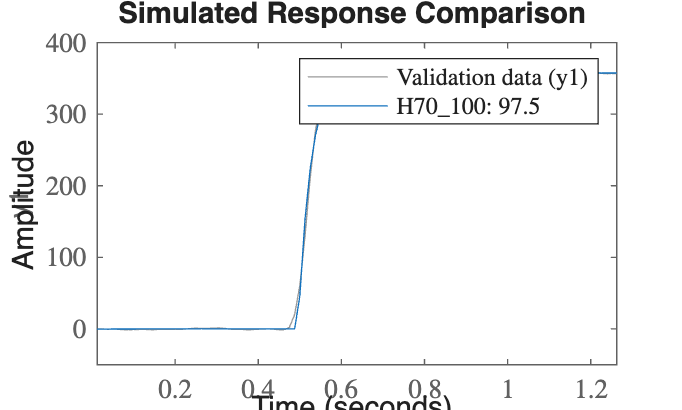

compare(H70_100,data);


% 100-70 HOT
data = iddata(thrust(11390:11490)-thrust(11390),throttle(11390:11490)-throttle(11390),1/80);
H100_70 = procest(data,'P1D')


H100_70 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 10.288                  
       Tp1 = 0.031997                
        Td = 0.034988                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 95.35%                     
FPE: 52.37, MSE: 49.35                             
 
<a href="matlab:if exist('H100_70','var'), if isa(H100_70,'idproc'), disp(' '); disp(get(H100_70)), else disp(' '); disp('Unable to display properties for variable H100_70 because it is no longer a/an idproc object.');, end, else matlab.graphics.internal.getForDisplay('H100_70'), end">Model Properties<

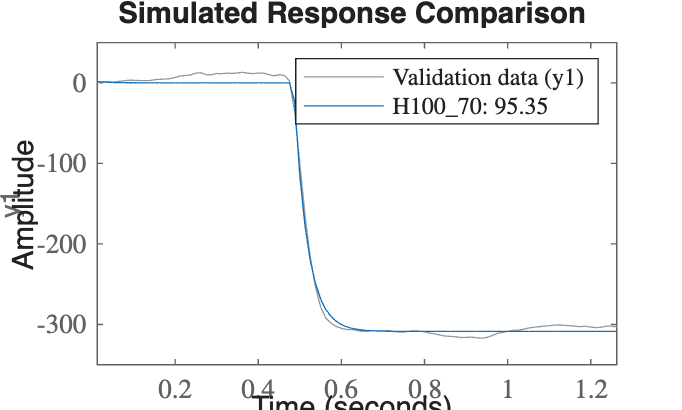

compare(H100_70,data);


% 70-40
data = iddata(thrust(11550:11650)-thrust(11550),throttle(11550:11650)-throttle(11550),1/80);
H70_40 = procest(data,'P1D')


H70_40 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 10.206                  
       Tp1 = 0.033816                
        Td = 0.03475                 
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 95.88%                     
FPE: 37.57, MSE: 35.4                              
 
Model Properties


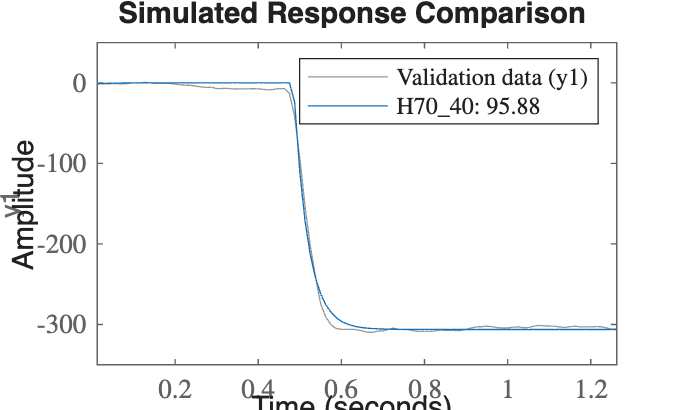

compare(H70_40,data);


% 40-10 HOT
data = iddata(thrust(11710:11810)-thrust(11710),throttle(11710:11810)-throttle(11710),1/80);
H40_10 = procest(data,'P1D')


H40_10 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 5.3263                  
       Tp1 = 0.035971                
        Td = 0.033975                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 95.8%                      
FPE: 10.74, MSE: 10.12                             
 
Model Properties


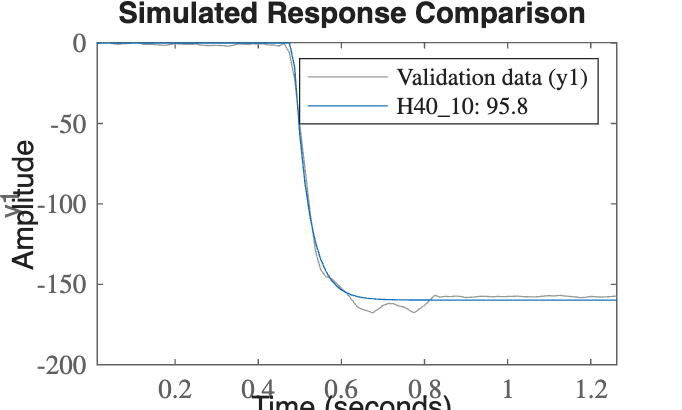

compare(H40_10,data);

Kp_c_3 = [C10_40.Kp C40_10.Kp C40_70.Kp C70_40.Kp C70_100.Kp C100_70.Kp];
Kp_h_3 = [H10_40.Kp H40_10.Kp H40_70.Kp H70_40.Kp H70_100.Kp H100_70.Kp];

array2table([Kp_c_3; Kp_h_3],"VariableNames",{'10-40', '40-10', '40-70', '70-40', '70-100', '100-70'}, "RowNames", {'Cold', 'Hot'})

ans = 2×6 table
            10-40     40-10     40-70     70-40     70-100    100-70
            ______    ______    ______    ______    ______    ______

    Cold    4.7686    5.1541    9.3538    9.4853    11.971    11.879
    Hot     5.0671    5.3263    9.3218    10.206    11.916    10.288



Tp_c_3 = [C10_40.Tp1 C40_10.Tp1 C40_70.Tp1 C70_40.Tp1 C70_100.Tp1 C100_70.Tp1];
Tp_h_3 = [H10_40.Tp1 H40_10.Tp1 H40_70.Tp1 H70_40.Tp1 H70_100.Tp1 H100_70.Tp1];

array2table([Tp_c_3; Tp_h_3],"VariableNames",{'10-40', '40-10', '40-70', '70-40', '70-100', '100-70'}, "RowNames", {'Cold', 'Hot'})

ans = 2×6 table
             10-40       40-10       40-70       70-40       70-100      100-70 
            ________    ________    ________    ________    ________    ________

    Cold      0.0296    0.036824    0.032415    0.034384    0.024314    0.032009
    Hot     0.034659    0.035971    0.041779    0.033816    0.029457    0.031997



Td_c_3 = [C10_40.Td C40_10.Td C40_70.Td C70_40.Td C70_100.Td C100_70.Td];
Td_h_3 = [H10_40.Td H40_10.Td H40_70.Td H70_40.Td H70_100.Td H100_70.Td];

array2table([Td_c_3;Td_h_3],"VariableNames",{'10-40', '40-10', '40-70', '70-40', '70-100', '100-70'}, "RowNames", {'Cold', 'Hot'})

ans = 2×6 table
             10-40       40-10       40-70       70-40       70-100      100-70 
            ________    ________    ________    ________    ________    ________

    Cold    0.055525    0.029925    0.043488    0.034212    0.044075    0.033575
    Hot     0.054775    0.033975    0.045425     0.03475    0.045925    0.034988
